# Stability Analysis of Dynamical Systems 

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours and analysis. A common linear model type is the state space model. 

Analysing the stability properties of a dynamical system is a core problem in control theory, as it rigoursely characterises when a system is "*well-behaved*" or not. This file introduces some of the basic tools used to determine stability of state-space systems.    As ever, use text books for more detail on the theoretical aspects.

Lots of code snippets are provided as examples of how MATLAB can be used and the intention is that readers can use these as exemplars and/or templates and change the models and scenarios for their own need.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by Ross Drummond, with some input from Anthony Rossiter,  Lanlan Su (University of Sheffield) and Ruth Bars ( Budapest University of Technology and Economics)  

                         

## Table of Contents

- Closed vs open systems

- Equilibrium points

- Vector norms

- Velocity field diagrams

- Stability of solutions

- Global vs. local stability

- Limit cycles

## 1. Closed vs. Open systems

To begin, we will specify the type of dynamical systems for which our notions of stabiltiy will be defined. In particular, the following notions of "*stability*" will be defined for **closed systems** where a feedback policy mapping inputs to states of the forn $$u(t) = \alpha(x(t))$$ has been found. This is in contrast to **open systems**, where the control input $$u(t)$$ is still a variable. Figure 1. characterises the difference between open and closed systems.

 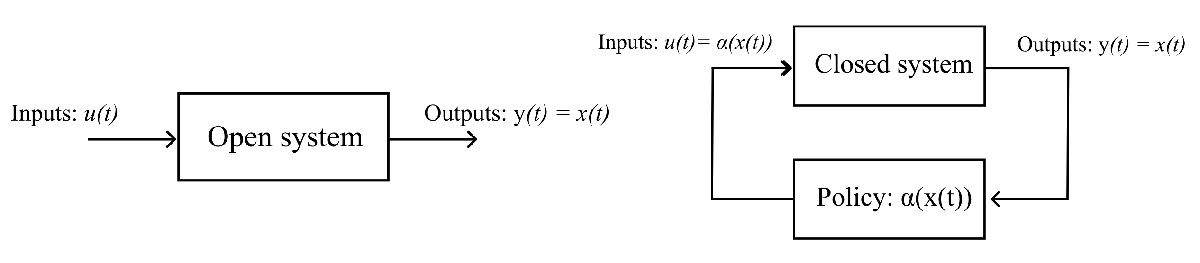

**Figure 1**: Open and closed systems

Mathematically, the dynamics of open systems are of the form: 


$$$$
\frac{dx(t)}{dt} = f_{o}(x(t),u(t))
$$$$


whilst those of closed systems are:

$$$
\frac{dx(t)}{dt} = f(x(t))
$$$.

We can convert open systems into closed ones by substituting $$u(t) = \alpha(x(t))$$ into the open dynamics, as in 

$$$
 f(x(t)) = f_o(x(t),\alpha(x(t)))
$$$.

By restricting our attention to closed systems, determining the stability of a system becomes a problem of determining whether the state variable $$x(t)$$ blows up or not (as in it whether it remains bounded as time goes on).

## 2. Eqiulibrium points

To determine whether a system is stable or not (as in, whether the state is getting "*bigger*" or not) we have to set a point around which  this notion of "*bigge*r" is defined. For this, we use an **equilibrium point. **

An equilibrium point, $x_e$, is a point in the state-space (as in a point such that $x(t) = x_e$) where the state remains fixed for all times. In other words,  an equilibrium point satisfies:


$$$$ f(x_e) = 0, $$$$


as this implies that $dx(t)/dt = 0$. Often, it is typical that the origin is an equilibrium point, and so $x_e = [0,\,0,\,\dots,\,0]^\top$, but other points may exist. For example, the equilibrium point of the system:


$$\left[\matrix{ \dot{x}_1(t) \cr \dot{x}_2(t)}\right] = 
\left[\matrix{-1 & 0 \cr 0  &2}\right]
\left[\matrix{ (3-{x}_1(t)) \cr (4-{x}_2(t))}\right] $$


is  $x_e = [3,\,4]^\top$. Nonlinear systems dynamics are more complex and may have multiple equilibrium points. For example, the following system motivated by a damped inverted pendulum:


$$\left[\matrix{ \dot{x}_1(t) \cr \dot{x}_2(t)}\right] = 
\left[\matrix{x_2(t)-0.2 x_1(t) \cr 9.81 \sin(x_1(t))}\right]$$


has equilibrium points at  $x_e = [n ~\pi,\, 0.2 n ~\pi]^\top$ for each $n = \dots,\,-2,\,-1,\,0,\,1,\,2,\,\dots$. The following code simulates this system for a couple of different initial conditions and the trajectories converge to different equilibrium points depending upon the initial condition.  

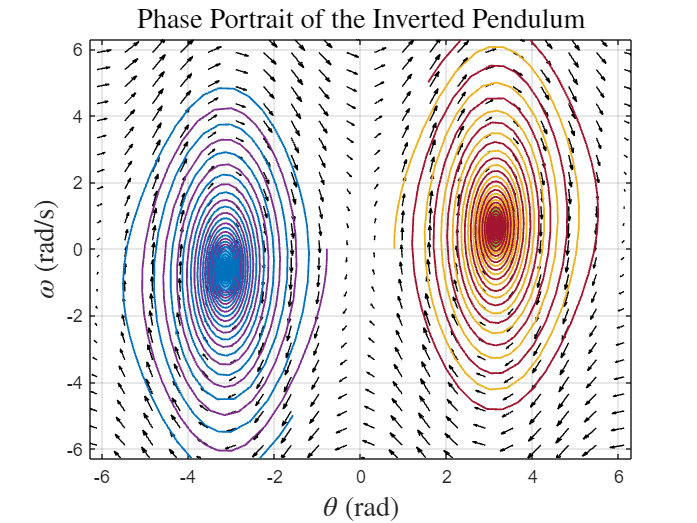

% Parameters
g = 9.81; % acceleration due to gravity (m/s^2)
L = 1.0; % length of the pendulum (m)

% Define the system of differential equations
inverted_pendulum = @(t, x) [x(2)-2e-1*x(1); (g/L) * sin(x(1))];

% Create a grid of initial conditions for the phase portrait
theta = linspace(-4*pi, 4*pi, 40);
omega = linspace(-10, 10, 40);
[T, W] = meshgrid(theta, omega);

% Compute the vector field
dT = W-2e-1*T;
dW = (g/L) * sin(T);

% Plot the vector field using quiver
figure;
quiver(T, W, dT, dW, 'k');
xlabel('$\theta$ (rad)','interpreter','latex','fontsize',15);
ylabel('$\omega$ (rad/s)','interpreter','latex','fontsize',15);
title('Phase Portrait of the Inverted Pendulum','interpreter','latex','fontsize',15);
grid on;
hold on;

% Define initial conditions
initial_conditions = [
    0, 0;          % Origin
    pi/4, 0;       % Small angle to the right
    -pi/4, 0;      % Small angle to the left
    pi, 0;         % Inverted position
    -pi, 0;        % Inverted position (other side)
    pi/2, 5;       % Large initial angular velocity
    -pi/2, -5;     % Large initial angular velocity (other side)
];

% Solve and plot trajectories for the initial conditions
for i = 1:size(initial_conditions, 1)
    [~, y] = ode45(inverted_pendulum, [0 1e3], initial_conditions(i, :));
    plot(y(:, 1), y(:, 2), 'LineWidth', 1);
end
axis([-2*pi 2*pi -2*pi 2*pi])

hold off;

## 3. Vector Norms

Another important concept in stability analysis is being precise in what we mean by unstable and stable. In other words, we have to be mathematically precise in how we define whether the state of our system is getting bigger or smaller. Whilst the concepts of "bigger" and "smaller" are fairly obvious for single numbers, (e.g. $2>1$ and so on), it is less obvious for the state vectors $x(t) \in \mathbb{R}^n$ which evolve in state-space systems. 

For example, how do we determine which of the following two vectors, $x$ and $y$, are bigger?


$$\[
x =[ 1,\, 1,\,  1], \quad y = [0.1, \,0.1,\,2] 
\]$$


If we take our idea of the size of a vector to be the sum of each component, then $x$ is larger. However, if we take it to be the biggest element in the vector, then $y$ is bigger. The nuances in how we determine the size of these two vectors implies we need some mathematical definitions to address this ambiguity. In this case, the solution to this is to use **vectors norms**.

A vector norm is a mathematical operation used to precisely determine a vector's size, with the flexibility in how we measure vectors' sizes (indicated by the example above) reflective in the variety of norms that may be specified. For a vector:


$$$x = [x_1,\,x_2, \, \dots, x_n]\in \mathbb{R}^n$$$


we denote its $$p$$**-norm** by the notation $\|x\|_p$. In this notation, $p$ is just some number which is used to represent how we measure the size of the  vector. The following gives three examples of vector norms for $p = 1,\,2,$ and $\infty$.

The $$2$$-norm of the vector $x$ is defined as the sum of the squares of each element, as in:

$\|x\|_2 = \sqrt{\sum^n_{i = 1}} {x_i}^2 = \sqrt{{x_1}^2+{x_2}^2+\dots +{x_n}^2}$.

This norm is the most popular in stability analysis problems, and is often called the Euclidean norm. Often, the short hand $\|x\|_2 = \|x\|$ is used since it is so common.

The $$1$
$-norm of the vector $x$ is defined as the sum of the absolute value of each element, as in:

$\|x\|_1 = \sqrt{\sum^n_{i = 1}} |{x_i}| =\sqrt{|{x_1}|+|{x_2}|+\dots +|{x_n}|}$.

The $\infty$-norm of the vector $x$ is defined as the maximum value of its elements, as in:

$\|x\|_\infty =\max_i{|x_i}| =\max\{{|{x_1}|,\,|{x_2}|,\,\dots,\,|{x_n}|\}$.

Figure 2 highlights the differences between these norms. For a vector of dimension $x  = [x_1,\,x_2] \in \mathbb{R}^2$, the blue line denotes the values where the $\infty$-norm = 1 (a box), the red line denotes the values where the $1$-norm = 1 (a diamond) , and the black line are the values where the $2$-norm = 1 (a circle). 

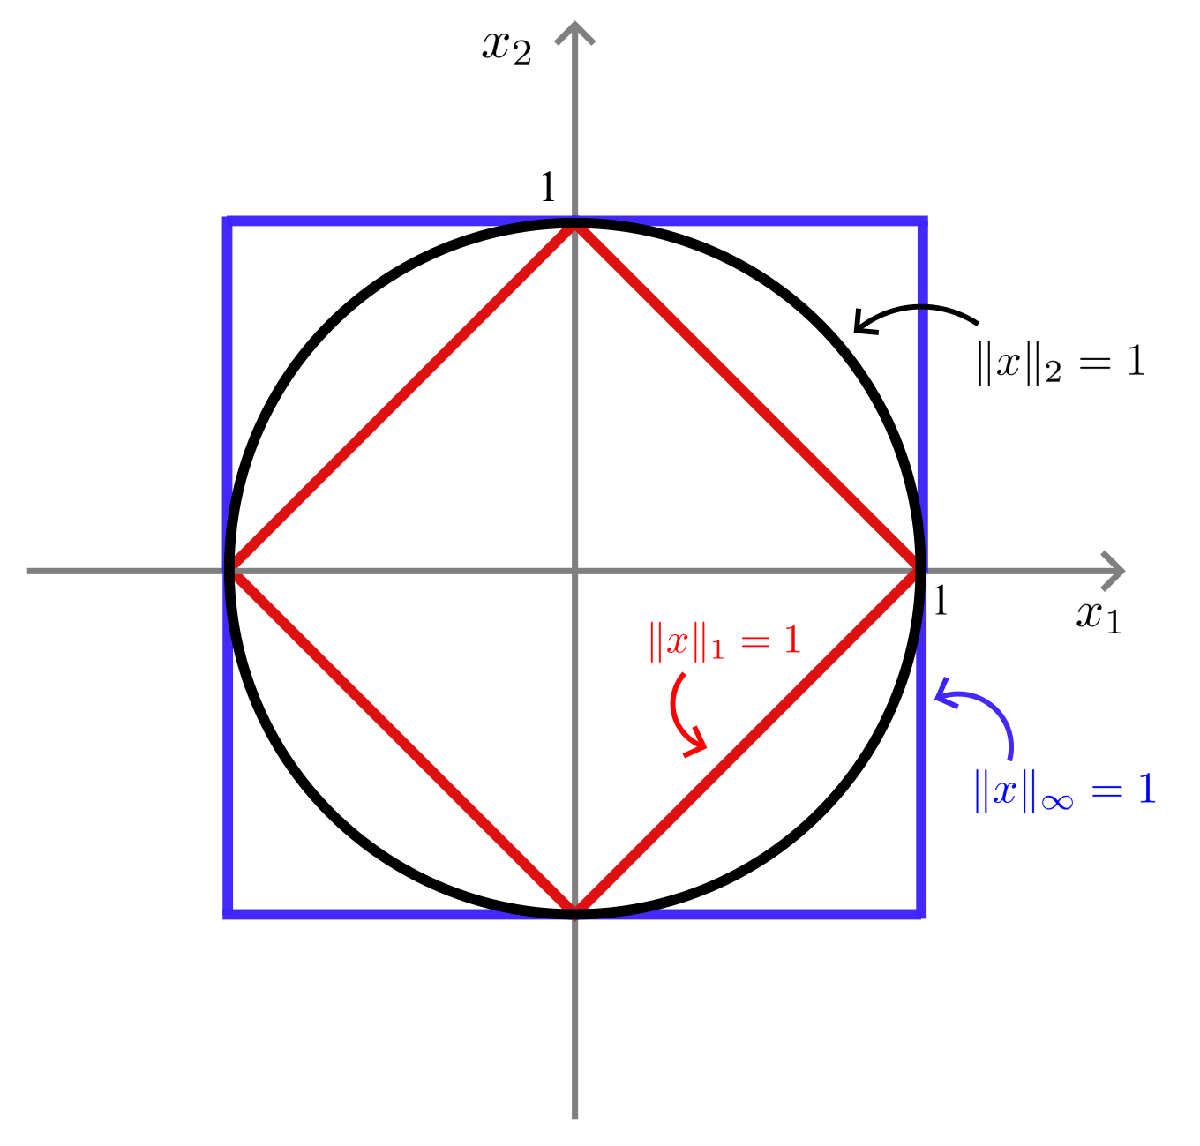

**Figure 2**: Illustration of different norms

The following code computes different norms for two vectors and compares their values. 

x = [1,1,1]; y = [0.1,0.1,2];
disp(['The 1-norm of x is ',num2str(norm(x,1))])

The 1-norm of x is 3


disp(['The 2-norm of x is ',num2str(norm(x,2))])

The 2-norm of x is 1.7321


disp(['The infty-norm of x is ',num2str(norm(x,inf))])

The infty-norm of x is 1



disp(['The 1-norm of y is ',num2str(norm(y,1))])

The 1-norm of y is 2.2


disp(['The 2-norm of y is ',num2str(norm(y,2))])

The 2-norm of y is 2.005


disp(['The infty-norm of y is ',num2str(norm(y,inf))])

The infty-norm of y is 2


## 4. Velocity field diagrams

We can now use the mathematical machinery of "vector norms" to define how big our state-space is getting around some equilibrium point, and so can begin to assess the stability of state-space systems. In general, determining stability of a system is quite a challenging problem, but qualitive solutions exist for some classes of system which make the problem much simpler. Specifically, for second order systems, as in those where the state is a two-dimensional vector with:

$\[\frac{dx(t)}{dt} = f(x(t)), \quad x(t) = [x_1(t),\,x_2(t)]^\top \in \mathbb{R}^2\]$,

we can get a qualitive understanding of the dynamics from plotting its **velocity field**.  With this approach, we just plot the vector $f(x(t))$ by sampling different points $x(t)$ and assessing its stability by seeing if the vectors are all pointing towards the equilibrium point or not.

For example, consider the second order system described by:

$\left[\matrix{ \dot{x}_1(t) \cr \dot{x}_2(t)}\right] = 
\left[\matrix{ x_2(t) \cr -x_1-x_2}\right]$.

This system would appear to be stable, as the following simulation show the trajectory converging towards an equilibrium point at the origin. 

disp('Section 4 below')

Section 4 below


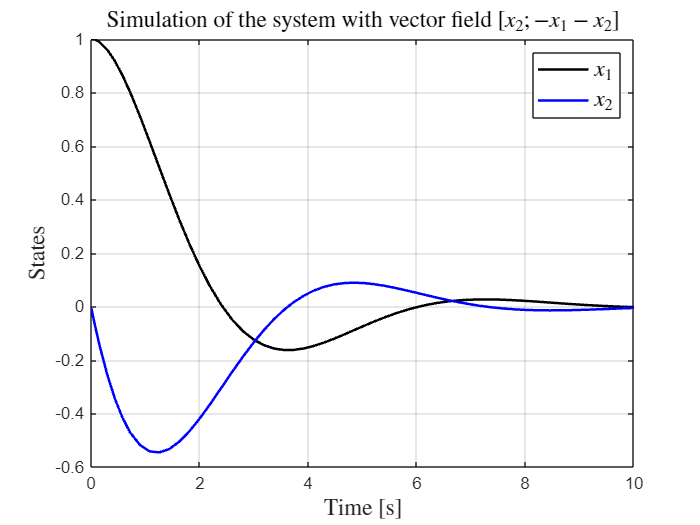

% Initial condition
x0 = [1; 0];

% Time span for simulation
tspan = [0 10];

% Solve the differential equation using ode45
[t, x] = ode45(@(t,x)[x(2); -x(1) - x(2)], tspan, x0);

% Plot the solution
figure;
plot(t, x(:,1), 'k', 'LineWidth', 1.5); hold on;
plot(t, x(:,2), 'b', 'LineWidth', 1.5);
xlabel('Time [s]','interpreter','latex','fontsize',14);
ylabel('States','interpreter','latex','fontsize',14);
title('Simulation of the system with vector field $[x_2; -x_1-x_2]$','interpreter','latex','fontsize',14);
leg = legend('$x_1$', '$x_2$');
set(leg,'interpreter','latex','fontsize',14)
grid on;

However, the above only plots one trajectory from one initial condition. With this method, we can not rule out that there is not another initial condition which would generate an unstable trajectory. As a work around, we can plot the vector field $f(x(t))$ at various points $x(t)$ and see if it is pointing towards the equilibrium point or not using the $\texttt{quiver}$ command.

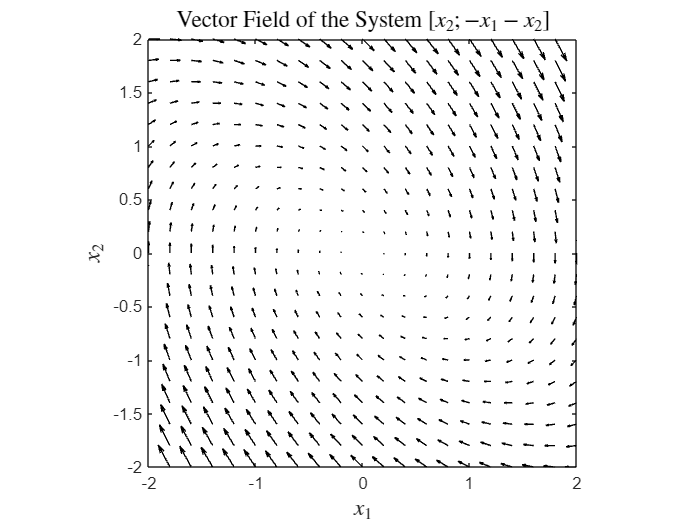

% Create a grid of points
[x1, x2] = meshgrid(-2:0.2:2, -2:0.2:2);

% Compute the vector field at each point
u = x2;
v = -x1 - x2;

% Plot the vector field using quiver
figure;
quiver(x1, x2, u, v, 'k'); hold on;
xlabel('$x_1$','interpreter','latex','fontsize',14);
ylabel('$x_2$','interpreter','latex','fontsize',14);
title('Vector Field of the System $[x_2; -x_1 - x_2]$','interpreter','latex','fontsize',14);
axis equal;
axis([-2 2 -2 2])

Notice that if we follow the arrows in this plot (which are the vector field the system flows around) then they eventually converge towards the origin. This would suggest that the system is stable and will converge to the origin as an equilibrium point. 

By contrast, consider the unstable system:

$\left[\matrix{ \dot{x}_1(t) \cr \dot{x}_2(t)}\right] = 
\left[\matrix{ 2x_1(t)-x_2(t) \cr -x_1+2x_2}\right]$.

The following code simulates this system and shows the solution growing exponentially.

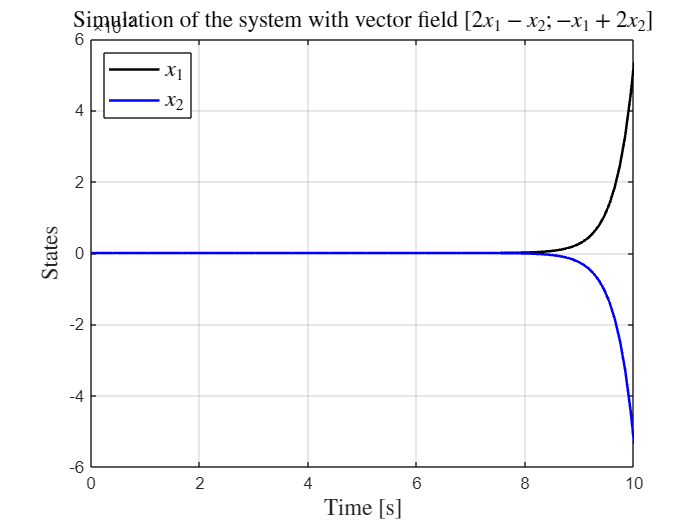

% Initial condition
x0 = [1; 0];

clear x;
% Time span for simulation
tspan = [0 10];

% Solve the differential equation using ode45
[t, x] = ode45(@(t,x)[2*x(1)-x(2); -x(1)+2*x(2)], tspan, x0);

% Plot the solution
figure;
plot(t, x(:,1), 'k', 'LineWidth', 1.5); hold on;
plot(t, x(:,2), 'b', 'LineWidth', 1.5);
xlabel('Time [s]','interpreter','latex','fontsize',14);
ylabel('States','interpreter','latex','fontsize',14);
title('Simulation of the system with vector field $[2x_1-x_2; -x_1+2x_2]$','interpreter','latex','fontsize',14);
leg = legend('$x_1$', '$x_2$');
set(leg,'interpreter','latex','fontsize',14,'location','northwest')
grid on;

Again, we can see why this is the case  by plotting its velocity field which shows the vector field pointing away from the origin.

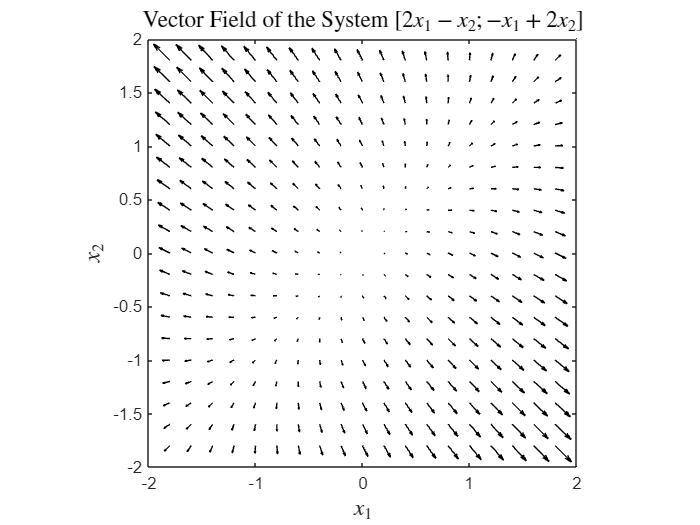

% Create a grid of points
[x1, x2] = meshgrid(-2:0.2:2, -2:0.2:2);

% Compute the vector field at each point
u = 2*x1-x2;
v = -x1 + 2*x2;

% Plot the vector field using quiver
figure;
quiver(x1, x2, u, v, 'k'); hold on;
xlabel('$x_1$','interpreter','latex','fontsize',14);
ylabel('$x_2$','interpreter','latex','fontsize',14);
title('Vector Field of the System $[2x_1-x_2; -x_1+2x_2]$','interpreter','latex','fontsize',14);
axis equal;
axis([-2 2 -2 2])

Thus by plotting the vector field, we can get an indication of the stability of a system and how it behaves. However, this approach suffers from two main drawbacks; i) it only works well for second order systems, and we cannot plot vector fields for higher dimension systems, as in those where $x = [x_1(t),\,x_2(t),\,x_3(t),\,x_4(t),\,x_5(t)]^\top$, ii) it is still only a qualitive description of stability, since there might still be points we have haven't sampled which generate unstable trajectories and these can not get ruled out. Therefore, we have to be more precise in how we define stability. 

## 5. Stability of solutions

To demonstrate the limitations of determining stability from sampling velocity fields, consider the following system described by the vector field:

$\left[\matrix{ \dot{x}_1(t) \cr \dot{x}_2(t)}\right] = 
\left[\matrix{ -|x_1(t)| \cr -\sin( x_2(t)) }\right]$.

If we sample the state-space in the region $x_1 \geq 0$, $|x_2| \leq \pi$, then the system looks stable. However, when $x_1 <0$, the system is unstable, as can be seen from the following simulations.

disp('Section 5 below')

Section 5 below


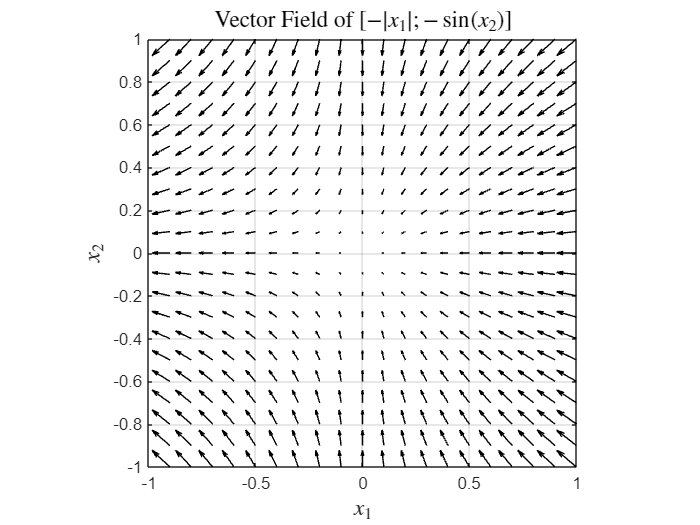

% Create a grid of points
limit = 1; delta = 0.1;
[x1, x2] = meshgrid(-limit :delta:limit, -limit :delta:limit );

% Compute the vector field at each point
u = -abs(x1);
v = -sin(x2);

% Plot the vector field using quiver
figure;
quiver(x1, x2, u, v, 'k');
xlabel('$x_1$','interpreter','latex','fontsize',14);
ylabel('$x_2$','interpreter','latex','fontsize',14);
title('Vector Field of  $[-|x_1|; -\sin(x_2)]$','interpreter','latex','fontsize',14);
axis equal;
axis([-1 1 -1 1]);
grid on;

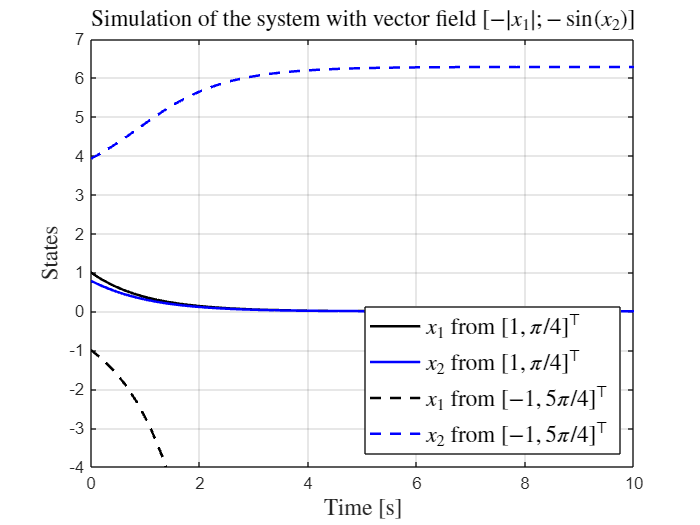


% Initial condition
x0 = [1; pi/4];
x0_2 = [-1; 5*pi/4];

clear x x_2;
% Time span for simulation
tspan = [0 10];

% Solve the differential equation using ode45
[t, x] = ode45(@(t,x)[-abs(x(1)); -sin(x(2))], tspan, x0);
[t_2, x_2] = ode45(@(t,x)[-abs(x(1)); - sin(x(2))], tspan, x0_2);

% Plot the solution
figure;
plot(t, x(:,1), 'k', 'LineWidth', 1.5); hold on;
plot(t, x(:,2), 'b', 'LineWidth', 1.5);
plot(t_2, x_2(:,1), '--k', 'LineWidth', 1.5); hold on;
plot(t_2, x_2(:,2), '--b', 'LineWidth', 1.5);
xlabel('Time [s]','interpreter','latex','fontsize',14);
ylabel('States','interpreter','latex','fontsize',14);
title('Simulation of the system with vector field $[-|x_1|; -\sin(x_2)]$','interpreter','latex','fontsize',14);
leg = legend('$x_1$ from $[1,\pi/4]^\top$', '$x_2$ from $[1,\pi/4]^\top$','$x_1$ from $[-1,5\pi/4]^\top$', '$x_2$ from $[-1,5\pi/4]^\top$');
set(leg,'interpreter','latex','fontsize',14,'location','southeast')
grid on;
axis([0 10 -4 7])

We then have to be careful with how we define stability. Using the notation $x(t;a)$ to indicate the trajectory of $x(t)$ from the initial condition $x(0) = a$, then the following definition can be used for stability:

$\forall\varepsilon >0, \exists \delta: \|b-a\|<\delta \Rightarrow \|x(t;b)-x(t;a)\| <\varepsilon, \quad  \forall t >0$.

Formally, this statements system says: "A solution $x(t)$ is stable if the 2-norm of $$x(t;a) $$  is *close* to that of $x(t;b)$."

For example, consider the system:

$\left[\matrix{ \dot{x}_1(t) \cr \dot{x}_2(t)}\right] = 
\left[\matrix{ -2x_1(t)+x_2(t) \cr x_1(t)-2x_2(t)}\right]$.

We can take $$b = [0,\,0]^\top$$ and evaluate how trajectories evolve around this equilibrium point. The following code computes how these trajectories evolve for different initial conditions, and suggets that these solutions are stable.

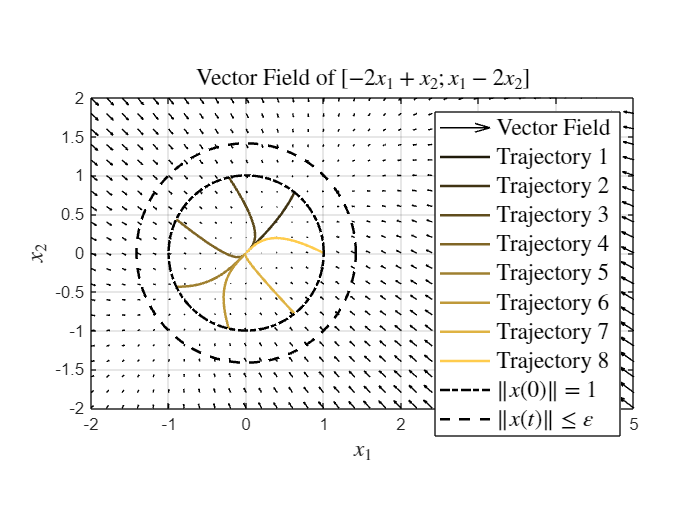

% Define the vector field function
vector_field = @(t, x) [-2*x(1) + x(2); x(1) - 2*x(2)];

% Create a grid of points for the quiver plot
[x1, x2] = meshgrid(-2:0.2:5, -2:0.2:5);

% Compute the vector field at each point
u = -2*x1 + x2;
v = x1 - 2*x2;

theta_plot = linspace(0,2*pi,1e2);

% Plot the vector field using quiver
figure;
quiver(x1, x2, u, v, 'k');
xlabel('$x_1$','interpreter','latex','fontsize',14);
ylabel('$x_2$','interpreter','latex','fontsize',14);
title('Vector Field of $[-2x_1 + x_2; x_1 - 2x_2]$','interpreter','latex','fontsize',14);
axis equal;
grid on;
hold on;

% Define initial conditions on the unit circle
theta = linspace(0, 2*pi, 8); % 8 points around the unit circle
initial_conditions = [cos(theta)', sin(theta)'];

% Solve and plot trajectories for each initial condition
tspan = [0, 5]; % Time span for simulation
for i = 1:size(initial_conditions, 1)
    [t, x] = ode45(vector_field, tspan, initial_conditions(i, :));
    plot(x(:, 1), x(:, 2),'color',[1 0.8 0.3]*(i)/size(initial_conditions, 1), 'LineWidth', 1.5);
    for j = 1:max(size(t))
    norm_x(j,i) = norm(x(j,:));
    end
end
plot(cos(theta_plot),sin(theta_plot),'-.k', 'LineWidth', 1.5);
plot(2^0.5*cos(theta_plot),2^0.5*sin(theta_plot),'--k', 'LineWidth', 1.5);

% Add legend
leg = legend('Vector Field', 'Trajectory 1', 'Trajectory 2', 'Trajectory 3', 'Trajectory 4', ...
       'Trajectory 5', 'Trajectory 6', 'Trajectory 7', 'Trajectory 8','$\|x(0)\|$ = 1','$\|x(t)\| \leq  \varepsilon$');
set(leg,'interpreter','latex','fontsize',14,'location','southeast');
hold off;
axis([-2 5 -2 2])

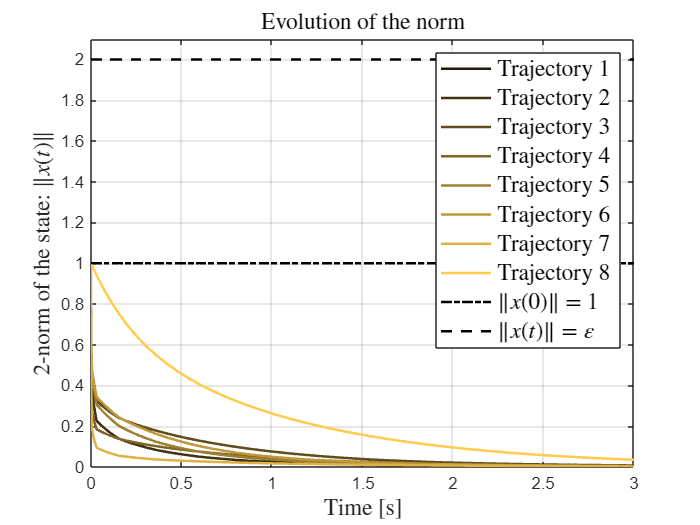


figure; hold  on;
for j = 1:size(initial_conditions, 1)
plot(t,norm_x(:,j),'-k','color',[1 0.8 0.3]*(j)/size(initial_conditions, 1), 'LineWidth', 1.5);
end
plot(t,ones(size(t)),'-.k', 'LineWidth', 1.5);
plot(t,2*ones(size(t)),'--k', 'LineWidth', 1.5);
xlabel('Time [s]','interpreter','latex','fontsize',14);
ylabel('2-norm of the state: $\|x(t)\|$','interpreter','latex','fontsize',14);
title('Evolution of the norm','interpreter','latex','fontsize',14);
leg = legend('Trajectory 1', 'Trajectory 2', 'Trajectory 3', 'Trajectory 4', ...
       'Trajectory 5', 'Trajectory 6', 'Trajectory 7', 'Trajectory 8','$\|x(0)\|$ = 1','$\|x(t)\| =  \varepsilon$');
set(leg,'interpreter','latex','fontsize',14,'location','northeast');
grid on;
hold on; box;
axis([0 3 0 2.1])

The definition of stability introduced above is quite relaxed, as it requires only that the trajectories remain "*close*" and do not necessarily converge towards each other. Often, we want to be more restrictive and require this extra convergence property. When this holds,  we say that the solutions are **asymptotically stable**. To be precise, we say that a solution is asymptotically stable if it is stable AND all nearby solutions converge to it. Note that all asympotically stable solutions are stable, but not all stable ones are asympotically stable (as the trajectories may not converge to each other; instead, they may just oscillate around each, for example, and never actually meet). But, since these solutions are still close and well-behaved, they can still be argued to be stable. 

The following code shows some examples of solutions which are: i) asympotically stable, ii) stable, and iii) unstable. Specifically, the following three systems are simulated, with each satisfying a different stability property,

$\left[\matrix{ \dot{x}_1(t) \cr \dot{x}_2(t)}\right] = 
\underbrace{\frac{1}{2}\left[\matrix{ -2x_1(t)+x_2(t) \cr -x_1(t)-3x_2(t)}\right]}_{\text{asymptotically stable}},
\qquad 
\left[\matrix{ \dot{x}_1(t) \cr \dot{x}_2(t)}\right] = 
\underbrace{\left[\matrix{ x_2(t) \cr -x_1(t)}\right]}_{\text{ stable}},
\qquad 
\left[\matrix{ \dot{x}_1(t) \cr \dot{x}_2(t)}\right] = 
\underbrace{\frac{1}{2}\left[\matrix{ 2x_1(t)+x_2(t) \cr -x_1(t)+3x_2(t)}\right]}_{\text{unstable}}$.

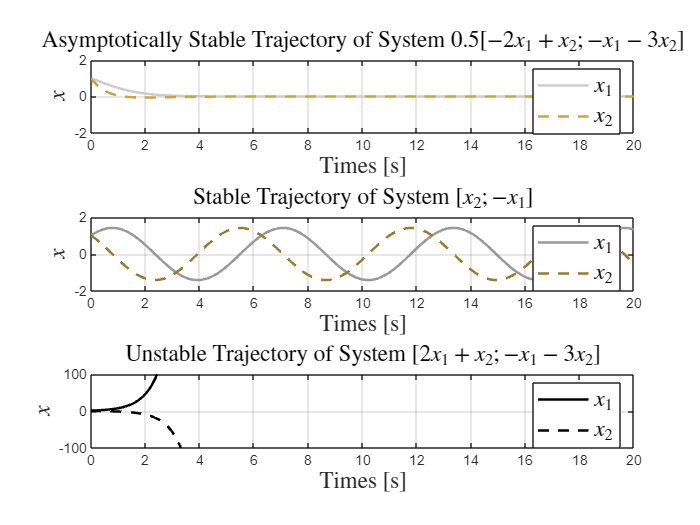

% Define the vector fields for each system
vector_field1 = @(t, x) 0.5*[-2*x(1) + x(2); -x(1) - 3*x(2)];
vector_field2 = @(t, x) [x(2); -x(1)];
vector_field3 = @(t, x)  [2*x(1) + x(2); -x(1) - 3*x(2)];

% Initial condition
initial_condition = [1; 1];

% Time span for simulation
tf = 20;
tspan = [0, tf];

% Solve the differential equations using ode45 for each system
[t1, x1] = ode45(vector_field1, tspan, initial_condition);
[t2, x2] = ode45(vector_field2, tspan, initial_condition);
[t3, x3] = ode45(vector_field3, tspan, initial_condition);

% Plot the trajectories
figure; color_1 = [1 1 1]; color_2 = [1 0.8 0.3];

% Plot for the first system
subplot(3, 1, 1); hold on;
plot(t1, x1(:, 1),'color',0.8*color_1, 'LineWidth', 1.5);
plot(t1, x1(:, 2),'--k','color',0.8*color_2, 'LineWidth', 1.5);
xlabel('Times [s]','interpreter','latex','fontsize',14);
ylabel('$x$','interpreter','latex','fontsize',14);
title('Asymptotically Stable Trajectory of System $0.5[-2x_1 + x_2; -x_1 - 3x_2]$','interpreter','latex','fontsize',14);
grid on; box;
axis([0 tf -2 2]);
leg = legend('$x_1$','$x_2$');
set(leg,'interpreter','latex','fontsize',14,'location','northeast');

% Plot for the second system
subplot(3, 1, 2); hold on;
plot(t2, x2(:, 1),'color',0.6*color_1, 'LineWidth', 1.5);
plot(t2, x2(:, 2),'--k','color',0.6*color_2, 'LineWidth', 1.5);
xlabel('Times [s]','interpreter','latex','fontsize',14);
ylabel('$x$','interpreter','latex','fontsize',14);
title('Stable Trajectory of System $[x_2; -x_1]$','interpreter','latex','fontsize',14);
grid on; box;
axis([0 tf -2 2]);
leg = legend('$x_1$','$x_2$');
set(leg,'interpreter','latex','fontsize',14,'location','northeast');

% Plot for the third system
subplot(3, 1, 3); hold on;
plot(t3, x3(:, 1),'color',0*color_1, 'LineWidth', 1.5);
plot(t3, x3(:, 2),'--k','color',0*color_2, 'LineWidth', 1.5);
xlabel('Times [s]','interpreter','latex','fontsize',14);
ylabel('$x$','interpreter','latex','fontsize',14);
title('Unstable Trajectory of System  $[2x_1 + x_2; -x_1 - 3x_2]$','interpreter','latex','fontsize',14);
grid on; box;
axis([0 tf -1e2 1e2]);
leg = legend('$x_1$','$x_2$');
set(leg,'interpreter','latex','fontsize',14,'location','northeast');

## 6. Global vs. Local stability

When a dynamical system generates solutions and trajectories that are stable (or unstable), we say that this system is stable (or unstable). However, some systems might only be stable in some region around the equilibrium point, and be unstable further away. When this occurs the system is said to be **locally stable**. By contrast, when it is stable everywhere, the system is said to be** globally stable**.

The following code plots the Van Der Pol oscillator going backwards in time. Here, there is a region near the origin which generates stable trajectories (shown in red) but outside this region, the trajectories are unstable (as can be seen from the directions of the velocity field).  This system is then only locally stable, and not globally stable.

disp('Section 6 below')

Section 6 below


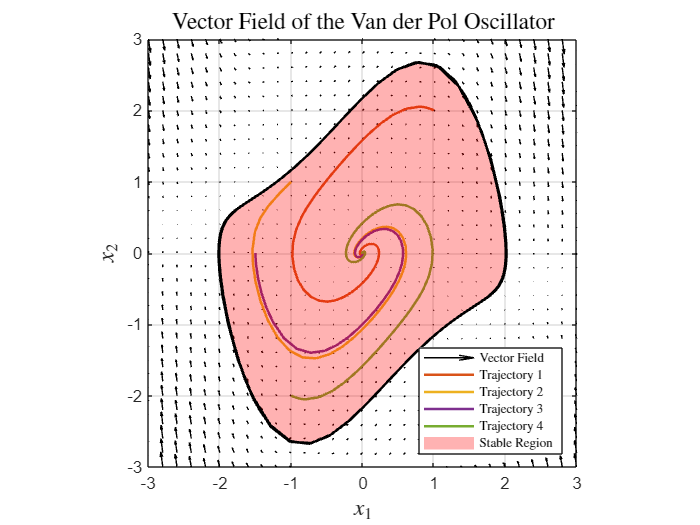

% Parameters
mu = 1.0; % Parameter for the Van der Pol oscillator

% Define the vector field function
vector_field = @(x1, x2) [-x2; -(mu * (1 - x1.^2) .* x2 - x1)];
vector_field_2 = @(x1, x2) [x2; mu * (1 - x1.^2) .* x2 - x1];

% Create a grid of points
[x1, x2] = meshgrid(-3:0.2:3, -3:0.2:3);

% Compute the vector field at each point
u = x2;
v = mu * (1 - x1.^2) .* x2 - x1;

% Plot the vector field using quiver
figure;
quiver(x1, x2, u, v, 'k');
xlabel('$x_1$','interpreter','latex','fontsize',14);
ylabel('$x_2$','interpreter','latex','fontsize',14);
title('Vector Field of the Van der Pol Oscillator','interpreter','latex','fontsize',14);
axis equal;
grid on;
hold on;

% Define initial conditions for the trajectories
initial_conditions = [1, 2; -1, 1; -1.5, 0; -1 -2];

% Solve and plot trajectories for each initial condition
tspan = [0, 20]; % Time span for simulation
[t_lc, x_lc] = ode45(@(t, y) vector_field_2(y(1), y(2)), tspan, [-1.00049277167432	1.15981531461658]);

for i = 1:size(initial_conditions, 1)
    [~, x] = ode45(@(t, y) vector_field(y(1), y(2)), tspan, initial_conditions(i, :));
    plot(x(:, 1), x(:, 2), 'LineWidth', 1.5);
end

% Highlight regions of stability and instability
% The Van der Pol oscillator is generally stable around the origin for small values of x1 and x2

% Define the region for stability (approximately within a unit circle for this example)
patch(x_lc(:, 1), x_lc(:, 2), 'red', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x_lc(:, 1), x_lc(:, 2),'color',[0 0 0], 'LineWidth', 1.5);

% Add some labels and legends for clarity
leg = legend('Vector Field', 'Trajectory 1', 'Trajectory 2', 'Trajectory 3', 'Trajectory 4', 'Stable Region');
set(leg,'interpreter','latex','fontsize',8,'location','southeast');
hold off;
axis([-3 3 -3 3])

## 7. Limit cycles

The definition of the stability of a trajectory in Section 3 is quite broad, as it includes system's whose trajectories don't necessarily converge towards the equilibrium point, but instead remain close to in the sense of the 2-norm. One particulatly interesting class of trajectories which are stable in this sense, but which are not necessarily asympotically stable, are **limit cycles**. 

A solution $x(t)$ is a limit cycle if it is periodic with some $T$>0, i.e. limit cycle captures oscillatory motion and satisfy:

$x(t+T) = x(t), \quad \forall t \geq 0$.

Examples of limit cycles are often encountered in nonlinear systems and descriptions of biological systems. An example is the following dynamical system which shows the oscillatory motion of a limit cycle:

$\left[\matrix{\dot{x}_1(t) \cr \dot{x}_2(t)}\right] = \left[\matrix{x_2(t)+x_1(1-{x_1}^2-{x_2}^2) \cr{-x_1+x_2(1-{x_1}^2-{x_2}^2) }}\right]$.

disp('Section 7 below')

Section 7 below


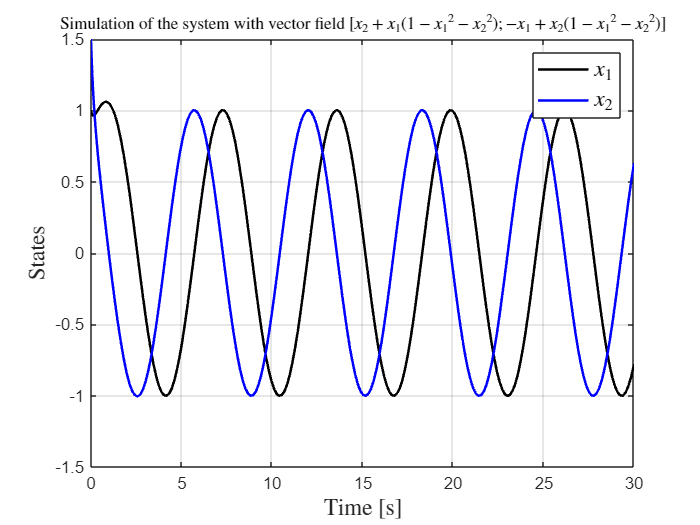

% Initial condition
x0 = [1,1.5]';

% Time span for simulation
tspan = [0 30];

% Solve the differential equation using ode45
vector_field_cycle = @(x1, x2) [x2+x1*(1-x1^2-x2^2); -x1+x2*(1-x1^2-x2^2)];
 [t, x] = ode45(@(t,x)vector_field_cycle(x(1),x(2)), tspan, x0);

% Create a grid of points
[x1, x2] = meshgrid(-1.8:0.1:1.8, -1.8:0.1:1.8);

% Compute the vector field at each point
u = x2+x1.*(1-x1.^2-x2.^2);
v = -x1+x2.*(1-x1.^2-x2.^2);

% Plot the solution
figure;
plot(t, x(:,1), 'k', 'LineWidth', 1.5); hold on;
plot(t, x(:,2), 'b', 'LineWidth', 1.5);
xlabel('Time [s]','interpreter','latex','fontsize',14);
ylabel('States','interpreter','latex','fontsize',14);
title('Simulation of the system with vector field $[x_2+x_1(1-{x_1}^2-{x_2}^2); -x_1+x_2(1-{x_1}^2-{x_2}^2)]$','interpreter','latex','fontsize',10);
leg = legend('$x_1$', '$x_2$');
set(leg,'interpreter','latex','fontsize',14)
grid on;

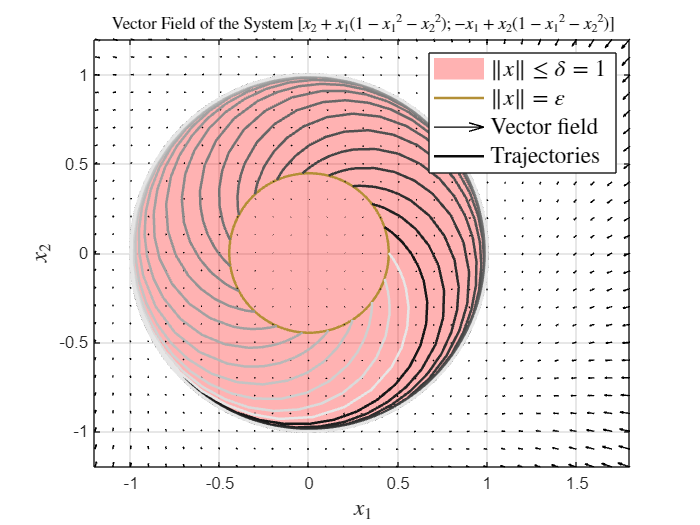


% Define initial conditions for the trajectories
theta = linspace(0, 2*pi, 20);
epsilon = 0.2;
x0_cycle = (epsilon^0.5)*cos(theta);
y0_cycle = (epsilon^0.5)*sin(theta);
initial_conditions_cycle = [x0_cycle' ,y0_cycle' ];

% Plot the vector field using quiver
figure; hold on;
theta = linspace(0, 2*pi, 100);
x_stable = cos(theta);
y_stable = sin(theta);
x_stable0 = (epsilon^0.5)*cos(theta);
y_stable0 = (epsilon^0.5)*sin(theta);

patch(x_stable, y_stable, 'red', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x_stable0, y_stable0, 'LineWidth', 1.5,'color',0.7*[1 0.8 0.3] );


quiver(x1, x2, u, v, 'k'); hold on;
for i = 1:size(initial_conditions_cycle, 1)
    [t, x] = ode45(@(t, y) vector_field_cycle(y(1), y(2)), tspan, initial_conditions_cycle(i, :)');
    plot(x(:, 1), x(:, 2), 'LineWidth', 1.5,'color',0.9*[1 1 1]*i/size(initial_conditions_cycle, 1));
end

xlabel('$x_1$','interpreter','latex','fontsize',14);
ylabel('$x_2$','interpreter','latex','fontsize',14);
title('Vector Field of the System $[x_2+x_1(1-{x_1}^2-{x_2}^2); -x_1+x_2(1-{x_1}^2-{x_2}^2)]$','interpreter','latex','fontsize',10);
leg = legend('$\|x\| \leq \delta = 1$','$\|x\| = \varepsilon$', 'Vector field','Trajectories');
set(leg,'interpreter','latex','fontsize',14)
axis equal;
grid on; box;
axis([-1.2 1.8 -1.2 1.2]);